# Localization and sensor fusion

For better understanding how Kalman Filter aplies to stimate Robot position See the video Part3, Prt4 and Part5 at URL: [https://es.mathworks.com/videos/series/understanding-kalman-filters.html](https://es.mathworks.com/videos/series/understanding-kalman-filters.html)

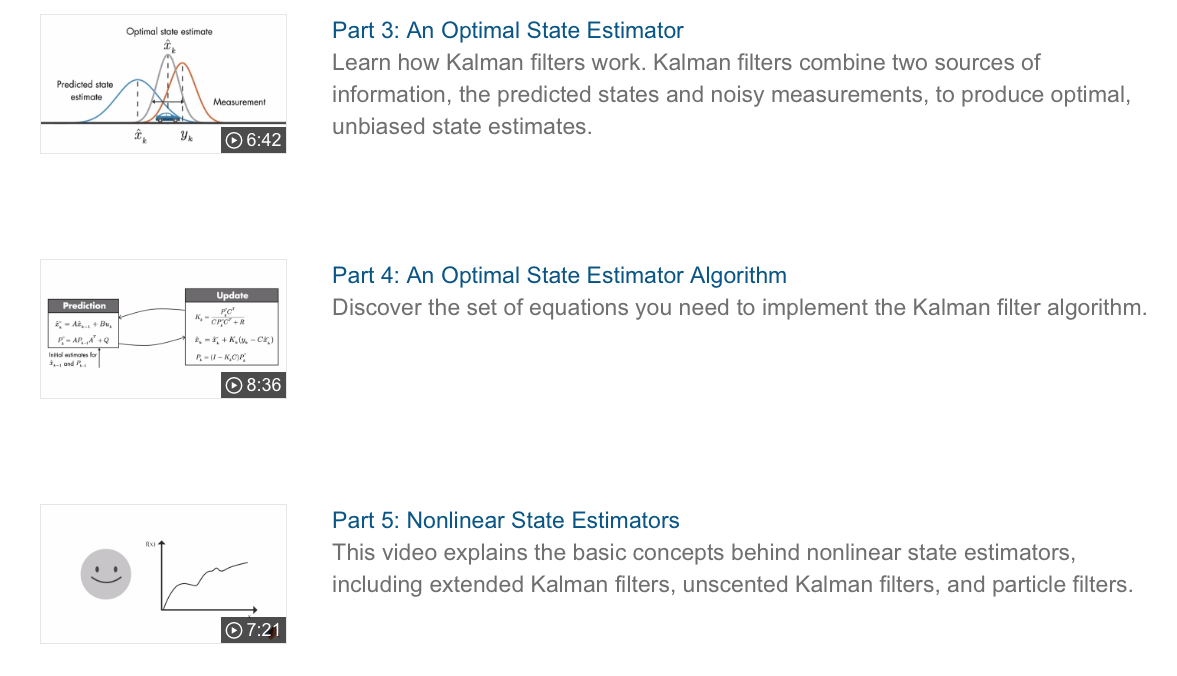

## Product of two PDF's 

Run the Live Script: ProductPDFs.mlx to check the sensor fusion concept

format compact
close all
clear
clc

## Estimating the tricycle pose 

### Using the tricycle model. Involved equations

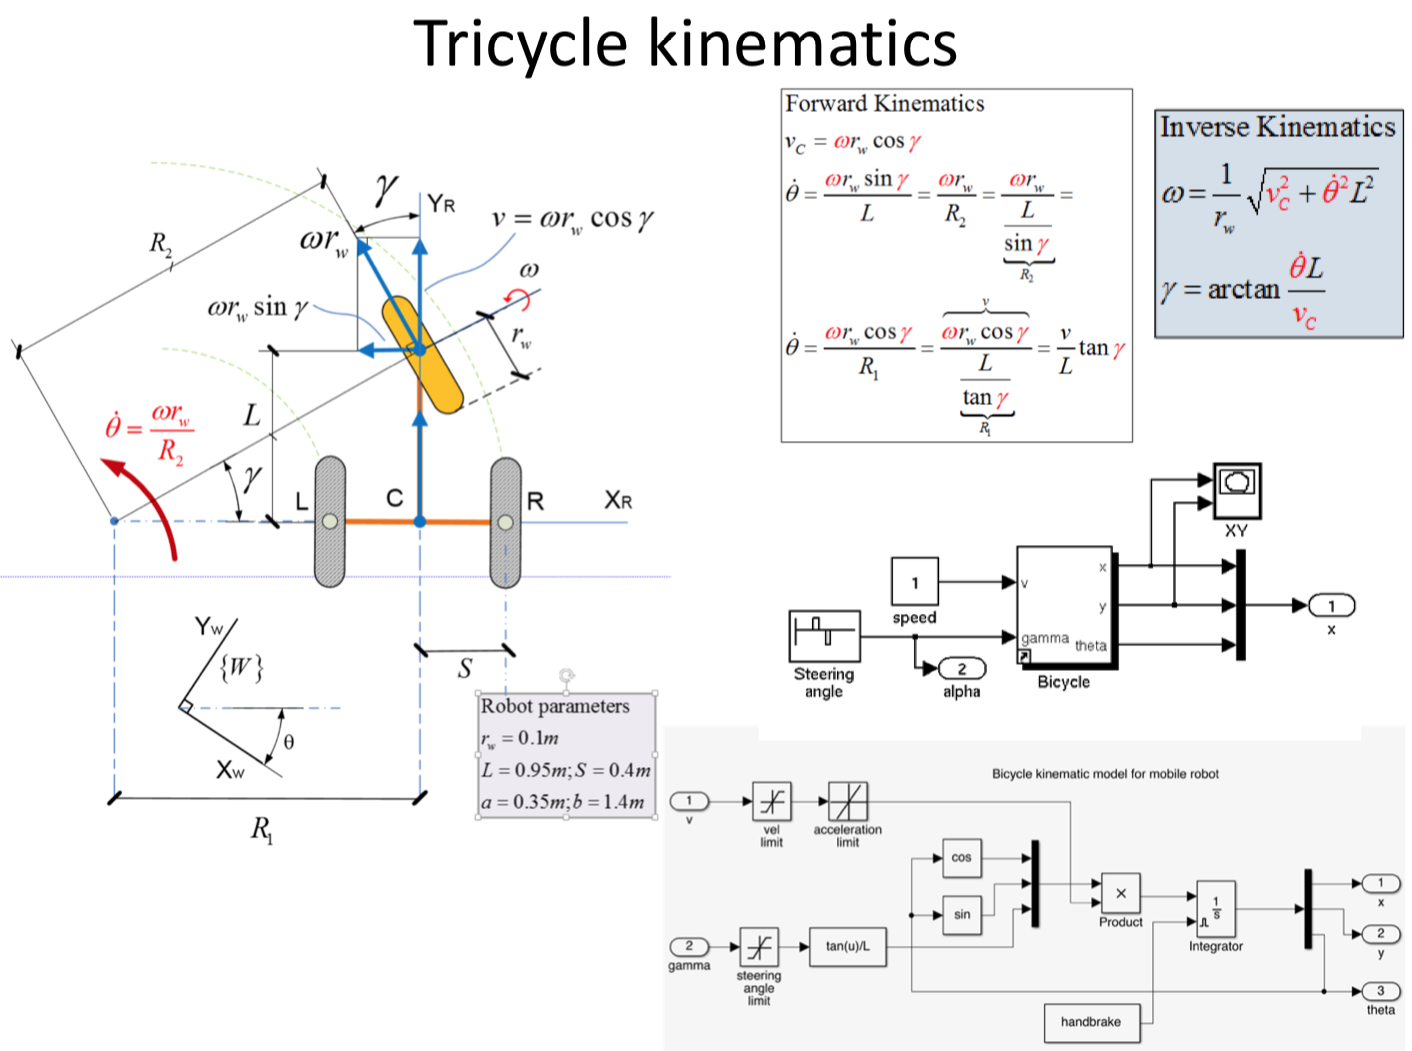

The Robotics ToolBox has some methods

V = diag([0.1, 0.7*pi/180].^2) % covariance matrix of noisy odometry

V =     0.0100         0
         0    0.0001


P0=0.0001*eye(3) % Probability Density Function (PDF) of Initial position

P0 = 	1.0e+-4 *

    1.0000         0         0
         0    1.0000         0
         0         0    1.0000


veh = Bicycle('covar', V) % Vehicle constructor 

veh = 
Bicycle object                      
  L=1, steer.max=0.5, accel.max=Inf 
  Superclass: Vehicle               
    max speed=1, dT=0.1, nhist=0    
    V=(0.01, 0.000149263)           
    configuration: x=0, y=0, theta=0


randinit % initialization of randon numbers
vel=1 % velocity

vel = 1

gamma=0.3 % steering angle

gamma = 0.3000

You think the odometry is:


$$\begin{array}{l}
\delta_d =v_c \Delta t=1\cdot \cos \left(\gamma \right)\cdot 0\ldotp 1\approx 0\ldotp 1\left\lbrack m\right\rbrack \\
\delta_{\theta } =\theta^˙ \Delta t=\frac{v}{L}\tan \left(\gamma \right)\cdot 0\ldotp 1\approx 0\ldotp 3\;\left\lbrack \textrm{rad}\right\rbrack 
\end{array}$$


But noise is there:

odo = veh.step(vel, gamma)

odo =     0.1538    0.0533


### Pose without Noise

You think the odometry is:


$$\begin{array}{l}
\delta_d =v_c \Delta t=1\cdot \cos \left(\gamma \right)\cdot 0\ldotp 1\approx 0\ldotp 1\left\lbrack m\right\rbrack \\
\delta_{\theta } =\theta^˙ \Delta t=\frac{v}{L}\tan \left(\gamma \right)\cdot 0\ldotp 1\approx 0\ldotp 3\;\left\lbrack \textrm{rad}\right\rbrack 
\end{array}$$
 

Pose: $\[{\xi _k} = trans{l_x}({\delta _d})tro{t_z}({\delta _\theta })\]$

Or


$$\dot \theta  = \frac{{{v_c}}}{L}\tan \left( \gamma  \right) \to \theta  = \int_0^t {\dot \theta } dt \\
  \dot x = {v_c}\cos \left( \theta  \right) \to x = \int_0^t {\dot xdt} \\
  \dot y = {v_c}\sin \left( \theta  \right) \to y = \int_0^t {\dot ydt}  \\ 
\end{gathered} \]$$


By hand

theta_d=vel*tan(gamma)/veh.L

theta_d = 0.3093

theta=theta_d*veh.dt

theta = 0.0309

next_pose_h=transl(vel*veh.dt,0,0)*trotz(theta)

next_pose_h =     0.9995   -0.0309         0    0.1000
    0.0309    0.9995         0         0
         0         0    1.0000         0
         0         0         0    1.0000


theta_h=tr2rpy(next_pose_h)

theta_h =          0         0    0.0309


Using the RTB (See method of 'veh' object)

Pose_t=veh.x'

Pose_t =     0.1000         0    0.0309


### With noise

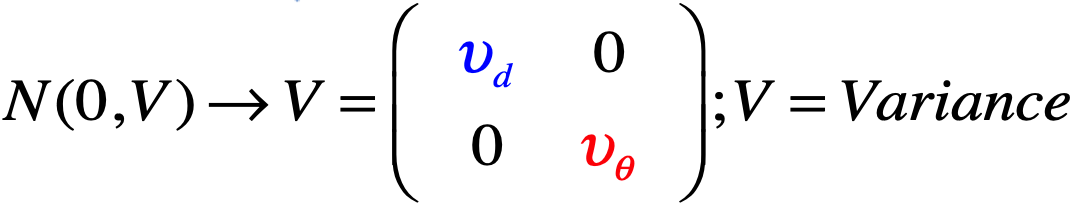

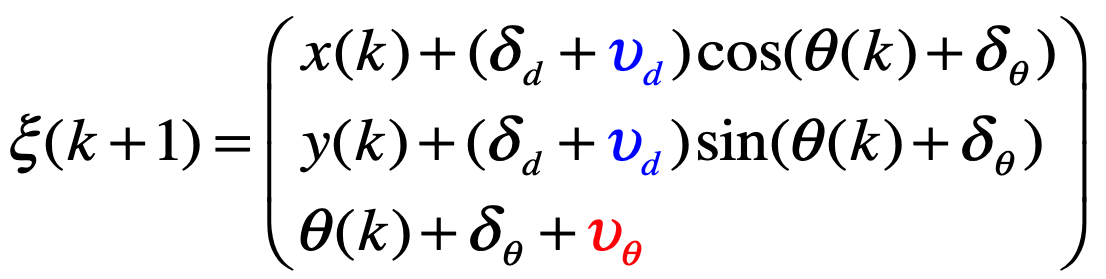

Using the RTB method (See Bicycle object/method '.f'). 

next_pose=veh.f([0 0 0], odo) % odo comes with noise

next_pose =     0.1535    0.0082    0.0533


By hand

x_next=0+odo(1)*cos(0+odo(2))

x_next = 0.1535

y_next=0+odo(1)*sin(0+odo(2))

y_next = 0.0082

theta_next=0+odo(2)

theta_next = 0.0533

next_pose=veh.f([1 2 0.1], odo) % odo comes with noise

next_pose =     1.1520    2.0235    0.1533


## Driving and running the simulation 

The vehicle is in a [-10 10 -10 10] enviroment and it move activating the throtel and the steering wheel

Ts=0.1

Ts = 0.1000

t=(0:Ts:50-Ts)' % aceleration time 

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


vel=1

vel = 1

v1= tpoly(0,vel,50)%t(1:50))

v1 =          0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461


v2= vel*ones(400,1)

v2 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


v3= tpoly(vel,0,50)%t(451:500))

v3 =     1.0000
    0.9999
    0.9994
    0.9979
    0.9952
    0.9909
    0.9848
    0.9767
    0.9664
    0.9539


vel=[v1;v2;v3]

vel =          0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461


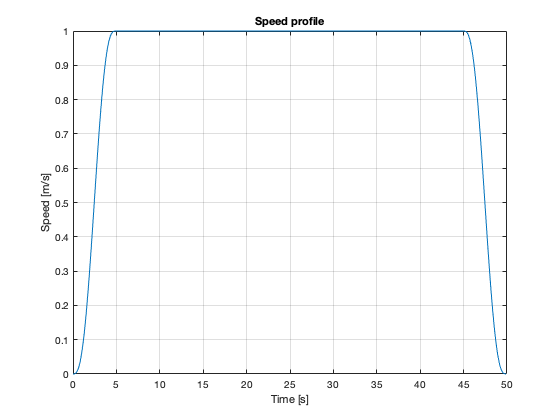

plot(t,vel)
grid on
title('Speed profile')
xlabel('Time [s]')
ylabel ('Speed [m/s]')

Running the simulation, which repeatedly calls the step method. The 'veh' object maintains a history of the true state of the vehicle. 

gg=0.3

gg = 0.3000

g1= tpoly(0,gg,50); % start steering 'cw'
g2= gg*ones(100,1); % been stered
g3= tpoly(gg,0,50);% Going back to no steered 
g4= zeros(100,1); % going straight
g5= tpoly(0,-gg,50); % start steering 'ccw'
g6= -gg*ones(100,1); % been stered
g7= tpoly(-gg,0,50);% Going back to no steered 
gamma=[g1;g2;g3;g4;g5;g6;g7]

gamma =          0
    0.0000
    0.0002
    0.0006
    0.0014
    0.0027
    0.0045
    0.0070
    0.0101
    0.0138


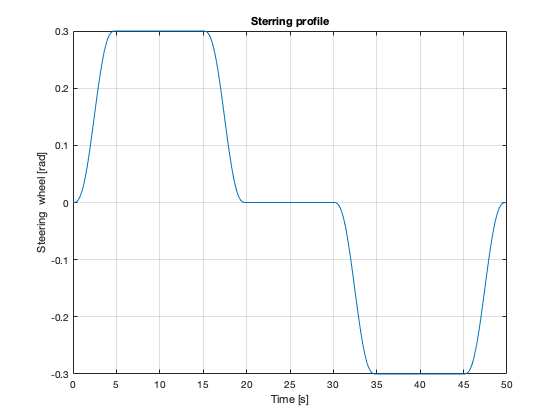

plot(t,gamma)
grid on
title('Sterring profile')
xlabel('Time [s]')
ylabel ('Steering  wheel [rad]')

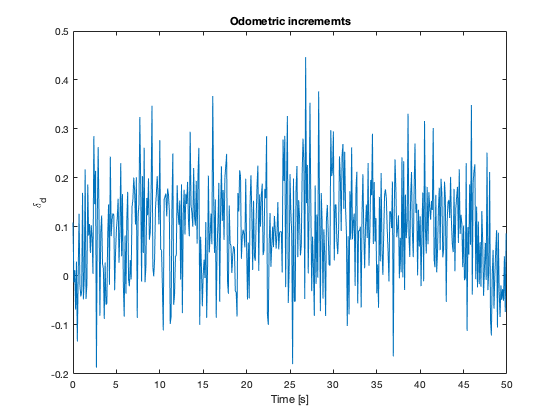

for i=1:500
odo(i,:) = veh.step(vel(i), gamma(i));
end
plot(t,odo(:,1));
title('Odometric incrememts')
xlabel('Time [s]')
ylabel('\delta_{d}')

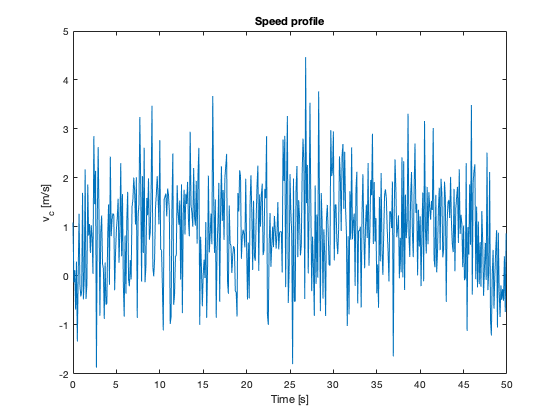

plot(t,odo(:,1)/Ts)
title('Speed profile')
xlabel('Time [s]')
ylabel('v_c [m/s]')

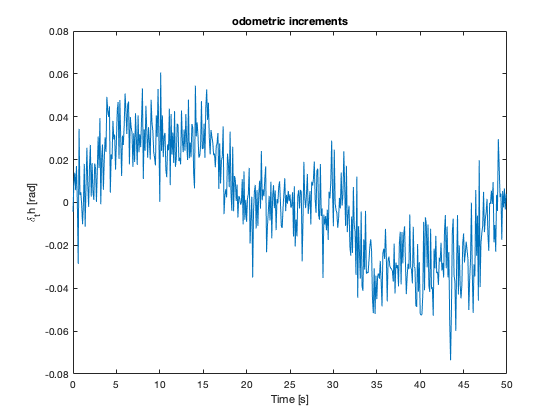

plot(t,odo(:,2));
title('odometric increments')
xlabel('Time [s]')
ylabel('\delta_th [rad]')

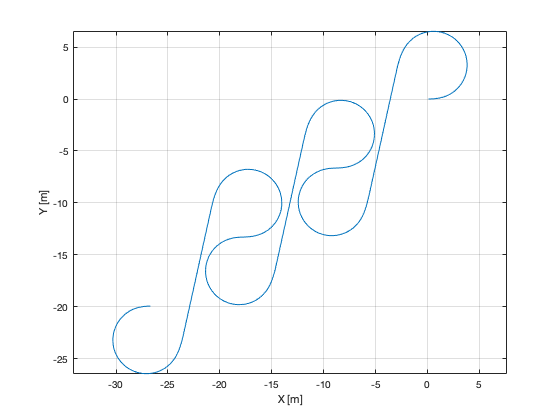

plot(veh.x_hist(:,1), veh.x_hist(:,2))
grid on
axis equal
xlabel('X [m]')
ylabel('Y [m]')

### Simulating to get the Taylor + Ricatti

sim("Tricycle_EKF_Pose_estimation.slx")

Ts = 0.1000

###  Plotting the results

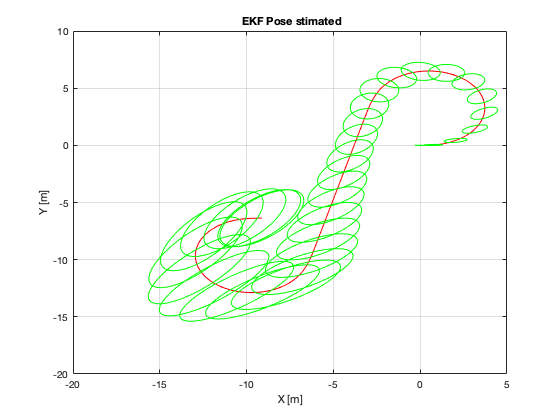

plot (Pose_t.Data(:,1),Pose_t.Data(:,2),'b');
grid on
title('Speed profile')
xlabel('X [m]')
ylabel('Y [m]')
hold on
plot (Pose_est.Data(:,1),Pose_est.Data(:,2),'r');

len=length(Pose_t.Data);
for  i=1:15:len
    plot_ellipse(Pk.signals.values(1:2,1:2,i),[Pose_est.Data(i,1), Pose_est.Data(i,2)],'g');
    title(' EKF Pose stimated');
end

## Map-based localization

I had a lot of problems to run this Live Script section into Matlab Online. 

I am not the only one, many other theacher report problems with method 'run' of the EKF object. Check you in the RTB forum of Peter Corke.

After fighting agains all possible RTB's and Matlab 2019b and 2020b I succed with Matlab 2019a with the RTB_10_3.

### Build the Map 

Known landmarks position randonly distributed

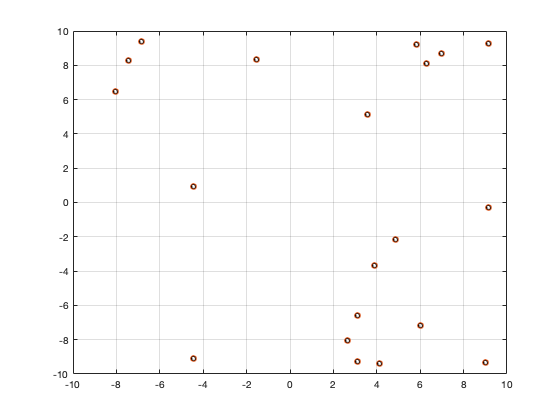

randinit % reset random number stream.
map = LandmarkMap(20,10); %N = 20 landmarks uniformly randomly spread over a region spanning ±10 m
map.plot()
scatter(map.map(1,:), map.map(2,:))

### Sensor data

$z=h\left(x,p_i \right)$; $x=\left(x_v \;y_v \;\theta_v \right)$ is the vehicle state and $p_i =\left(x_i \;y_i \right)$is is the known location of the ith landmark in the world frame.

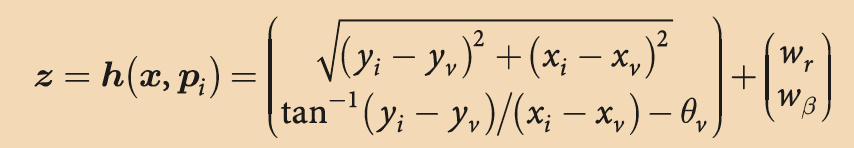

z = (r, β )' r is the distance to the landmark an β is bearing the robot see the landmark

w = (wr, wβ )T is a zero mean Gaussian random variable that models errors in the sensor

W = diag([0.1, 1*pi/180].^2); % Noise measurement

### Sensor on the vehiche

The Robotics ToolBox has the sensor Object with 'Methods'

sensor = RangeBearingSensor(veh, map, 'covar', W)

sensor = 
RangeBearingSensor sensor class:
LandmarkMap object              
  20 landmarks                  
  dimension 10.0                
W = [0.01 0;0 0.000305]         
interval 1 samples              


### Reading the sensor - 'errors ' 

The landmark is chosen randomly from the set of visible landmarks. z = distance and bearing and i the Landmark ID

[z,i] = sensor.reading() % return distance and angle

z =    24.9251
    0.3845


i = 17

map.landmark(17) % position of Land Mark (m)

ans =    -4.4615
   -9.0766


The robot can estimate the range and bearing angle to the landmark based on its own estimated position and the known position of the landmark from the map. 

Any difference between the observation z# and the estimated observation indicates an error in the robot’s pose estimate ' – it isn’t where it thought it was.


$$\[\nu  = {z^\# }\left\langle {k + 1} \right\rangle  - h\left( {{{\hat x}^ + }\left\langle {k + 1} \right\rangle ,{p_i}} \right)\left\{ {\begin{array}{*{20}{c}}
  {{z^\# }\left\langle {k + 1} \right\rangle  \to Sensor{\text{ }}reading} \\ 
  {h\left( {{{\hat x}^ + }\left\langle {k + 1} \right\rangle ,{p_i}} \right) \to Robot\;stimate} 
\end{array}} \right.\]$$



$$\nu \;\textrm{is}\;\textrm{the}\;\textrm{innovation}$$


## Laser innovation & making the fusion

randinit
map = LandmarkMap(20,10);
veh = Bicycle('covar', V);
veh.add_driver( RandomPath(map.dim) );
sensor = RangeBearingSensor(veh, map, 'covar', W, 'angle', ...
[-2*pi/3 2*pi/3], 'range', 4, 'animate');

### Prediction: Taylor and Riccati


$${{\hat x}_{k + 1}} = {{\hat x}_k} + {F_x}({x_k} - {{\hat x}_k}) + {F_v}{\nu _k} \\
  {P_{k + 1}} = {F_{xk}}{P_k}F_{xk}^T + {F_{vk}}VF_{vk}^T \\ 
\end{gathered} \]$$


### Updating

When posssible if land marks are visibles the innovation allows to update

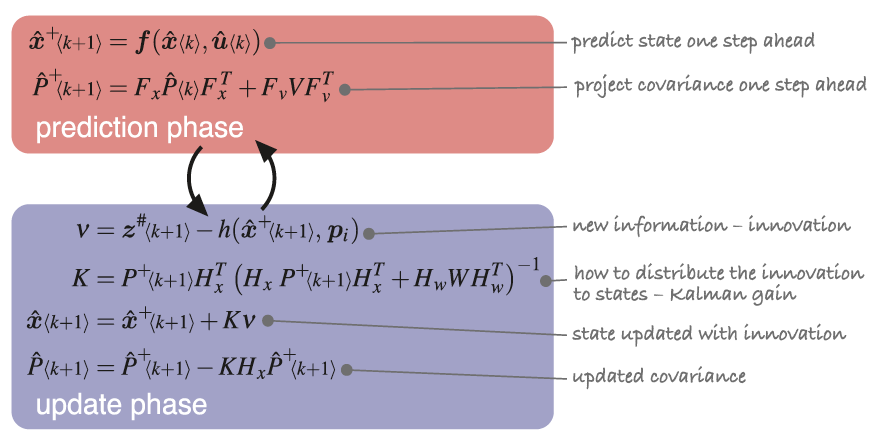

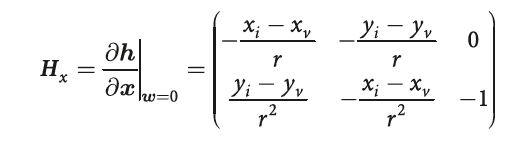

ekf=EKF(veh, V, P0, sensor, W, map); % constructor of the EKF object
%ekf.run(1000); % run the simulation Predicting and updating. 

In case your enviroment fails:

See video:https://drive.google.com/file/d/1PIg86QQqi5GCic19OeUx_2UzZMGcMqZs/view?usp=sharing

Load the Workspace ( EKF_Section.mat) to plot results. Check the pdf 'Senssor_fusion and _Localization.pdf'

### Plotting trajectories and ellipse errors

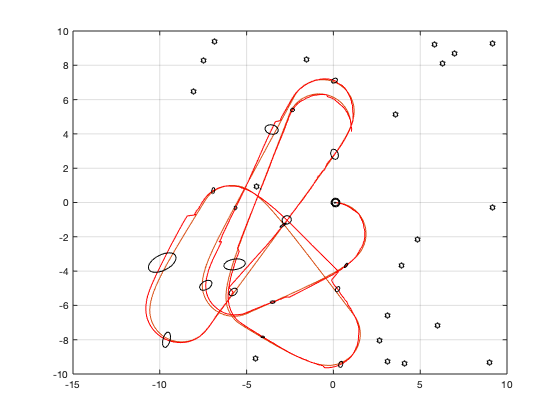

map.plot() % plot the map with the land marks
veh.plot_xy(); % Theoric trajectory
ekf.plot_xy('r'); % updated trajectory
ekf.plot_ellipse('k') % viasualizing the 2D ellipses

### Plotting statistics

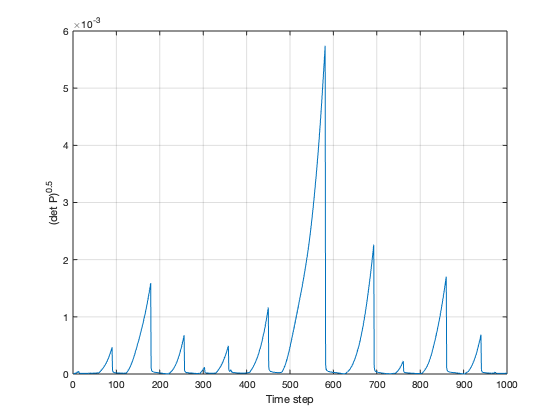

clf
ekf.plot_P() % compact way to see the coovariance 
xlabel('Time step'); ylabel('(det P)^{0.5}'); grid

Covariance magnitude as a function of time. Overall uncertainty is given by $\sqrt{\textrm{det}\left(P_k \right)}$and shows that uncertainty does not

continually increase with time.

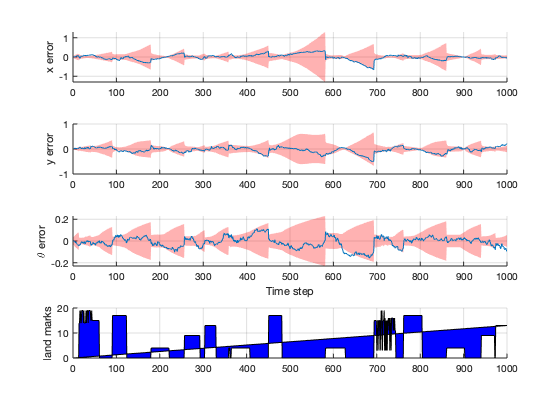

clf
ekf.plot_error('confidence', 0.95, 'nplots', 4) % errors x,y,theta  
plot_poly([1:1000; sensor.landmarklog], 'fill', 'b')% which landmark
ylabel('land marks')
grid

Top: pose estimation error with 95% confi dence bound shown in pink; bottom: observed landmarks the bar indicates which  landmark is seen at each time step, 0 means no observation.